% Lab 3 Task 4 - Transient behaviour of Bulb Box
clear all;
clf;
ports = serialportlist;
pb = PyBench(ports(end)); % create a PyBench object

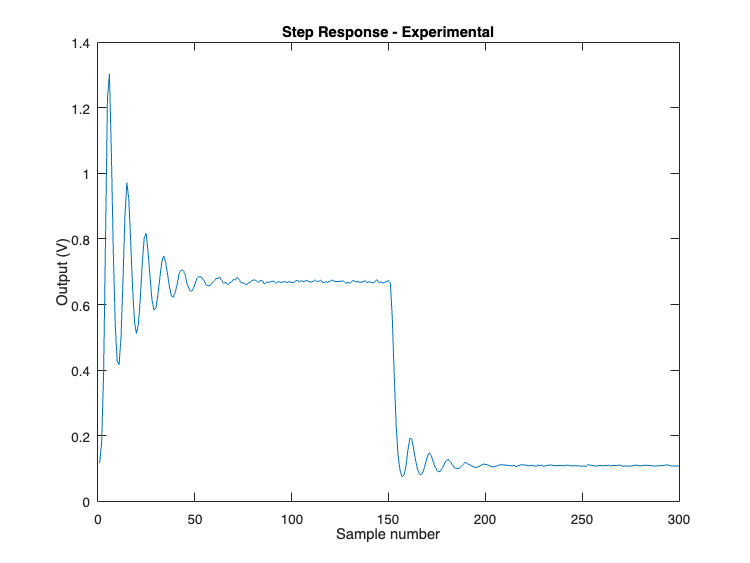


% set various parameters
fs = 50;
pb = pb.set_samp_freq(fs);
x_min = 0.7;
x_max = 1.2;
N = 150; % no of data samples

% Capture step response
pb.dc(x_min); % initial bulb value
pause(1); % wait 1 sec for it to settle
pb.dc(x_max); % rising step to bulb
rise = pb.get_block(N); % capture N samples
pb.dc(x_min); % falling step to bulb
fall = pb.get_block(N); % capture another N samples
data = [rise' fall']; % combine rise with fall

% plotting
figure(1);
clf;
plot(data);
xlabel('Sample number');
ylabel('Output (V)');
title('Step Response - Experimental');

fclose(instrfind()); % close the port